clear; clc;

Fs = 60e6; Ts = 1/Fs;  % 60 MHz, nyquist is 30 MHz
T = 20e-6; % Chirp duration, 20 us
t = 0:Ts:T-Ts; % 

f1 = 10e6; f2 = 20e6; % Chirp ramps up from 10 to 20 MHz 
fLO = 15e6;
M = 2;
Nfft = 8192;
f_xlim = [-40 40]; % plot xlims

% Helper: spectrum in MHz (Hann window, dB)
spec = @(sig,Fsamp) deal( ...
    linspace(-Fsamp/2, Fsamp/2, Nfft)/1e6, ...
    20*log10(abs(fftshift(fft((sig(:).*hann(numel(sig)))', Nfft))) + 1e-12));

x = chirp(t, f1, T, f2, 'linear'); % 10..20 MHz
lo = cos(2*pi*fLO*t); % +/- 15 MHz
y_mix = x .* lo;  % sum image goes from 25..35, difference image goes from -5..5 MHz

% Before decimation, remove energy above new nyquist freq
% new nyquist = 30 Mhz /2 = 15 Mhz
Fs2 = Fs/M;
N = 96; Fc = 8e6;   % cutoff of 8 Mhz keeps the -5..5 MHz chirp
b = fir1(N, Fc/(Fs2)); % Hamming LPF
y_lp = filter(b,1,y_mix); % filtered

% decimation
y_ds = y_lp(1:M:end);

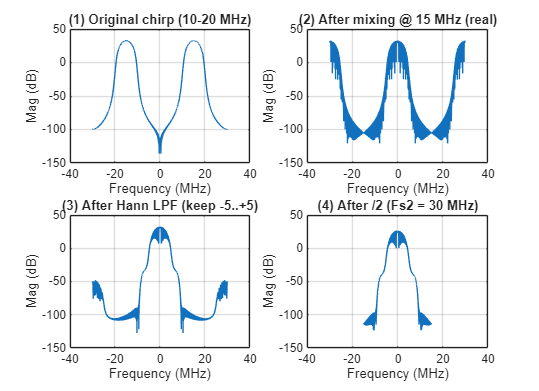

% Plotting
[fx, XdB] = spec(x, Fs);        % Original chirp
[fm, MdB] = spec(y_mix, Fs);    % Mixed chirp
[ff, LdB] = spec(y_lp, Fs);     % Filtered chirp
[fd, DdB] = spec(y_ds, Fs2);    % Downsampled chirp

figure('Color','w','Position',[70 70 1020 740]);
subplot(2,2,1); plot(fx, XdB); grid on; xlim(f_xlim);
title('(1) Original chirp (10-20 MHz)'); xlabel('Frequency (MHz)'); ylabel('Mag (dB)');

subplot(2,2,2); plot(fm, MdB); grid on; xlim(f_xlim);
title('(2) After mixing @ 15 MHz (real)'); xlabel('Frequency (MHz)'); ylabel('Mag (dB)');

subplot(2,2,3); plot(ff, LdB); grid on; xlim(f_xlim);
title('(3) After Hann LPF (keep -5..+5)'); xlabel('Frequency (MHz)'); ylabel('Mag (dB)');

subplot(2,2,4); plot(fd, DdB); grid on; xlim(f_xlim);
title('(4) After /2 (Fs2 = 30 MHz)'); xlabel('Frequency (MHz)'); ylabel('Mag (dB)');

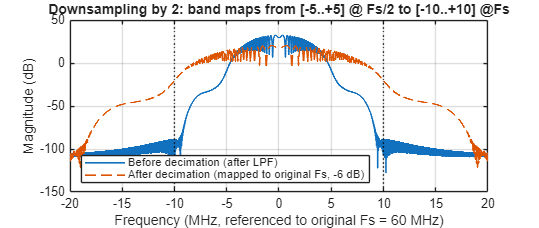

% Compare to original Fs axis
[ff0, Ypre_dB] = spec(y_lp, Fs);    % Filtered chirp
[fd2, Ypost_dB] = spec(y_ds, Fs2);  % Downsampled chirp

fd2_on_Fs = fd2 * M;                % map to original Fs axis
Ypost_on_Fs_dB = Ypost_dB - 6;      % 1/2 amplitude

figure('Color','w','Position',[120 120 900 380]);
plot(ff0, Ypre_dB, 'LineWidth',1.2); hold on; grid on;
plot(fd2_on_Fs, Ypost_on_Fs_dB, '--', 'LineWidth',1.2);
xline([-10 10], ':k');              % Expected -10..+10 MHz on original axis
xlim([-20 20]); xlabel('Frequency (MHz, referenced to original Fs = 60 MHz)');
ylabel('Magnitude (dB)');
title('Downsampling by 2: band maps from [-5..+5] @ Fs/2 to [-10..+10] @Fs');
legend('Before decimation (after LPF)','After decimation (mapped to original Fs, -6 dB)' ...
    ,Location='southwest');